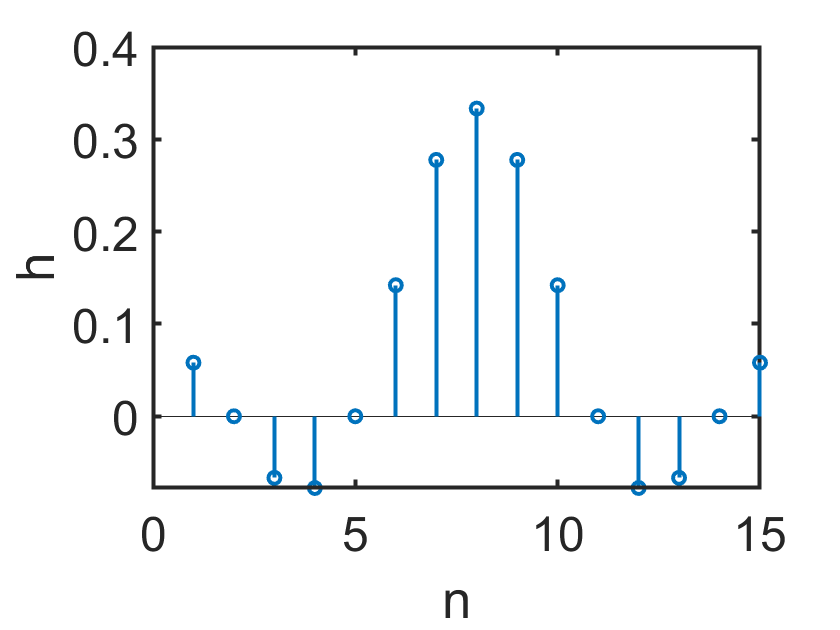

%FIR Filter Design
%Derya Malak, Nov 23, 2020

clear; clc; close all

%Method I: Frequency sampling

N = 15;      %number of taps
M = (N-1)/2;
wc = pi/3; %cutoff frequency of the low pass filter
%0.4*pi

w = 2*pi/N*(0:N-1); %samples of frequency axis

%Amplitude response
A = (w<=wc) | (w>=2*pi-wc); %note the symmetry (ignoring the DC element)

Theta = -M*w; %linear phase

H = A.*exp(1i*Theta); %N tap filter we design

h = real(ifft(H)); %real 

%Impulse response
stem(h)
xlabel('n'); ylabel('h')
set(gca,'FontSize',24)  %enlarge figure font size
set(findall(gcf,'-property','linewidth'),'linewidth',2) %makes the lines visible

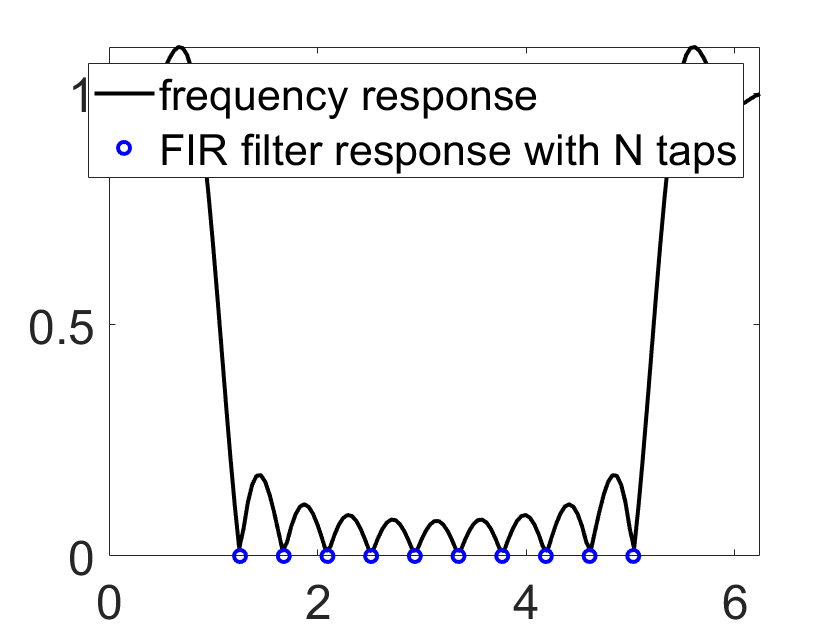


%Frequency response
wset = 2*pi/151*(0:150); %from 0 to 2pi
Hout = freqz(h,1,wset);
figure
plot(wset,abs(Hout),'k','linewidth',2);
hold on
plot(w,A,'bo','linewidth',2)
legend('frequency response','FIR filter response with N taps')
set(gca,'FontSize',24)  %enlarge figure font size

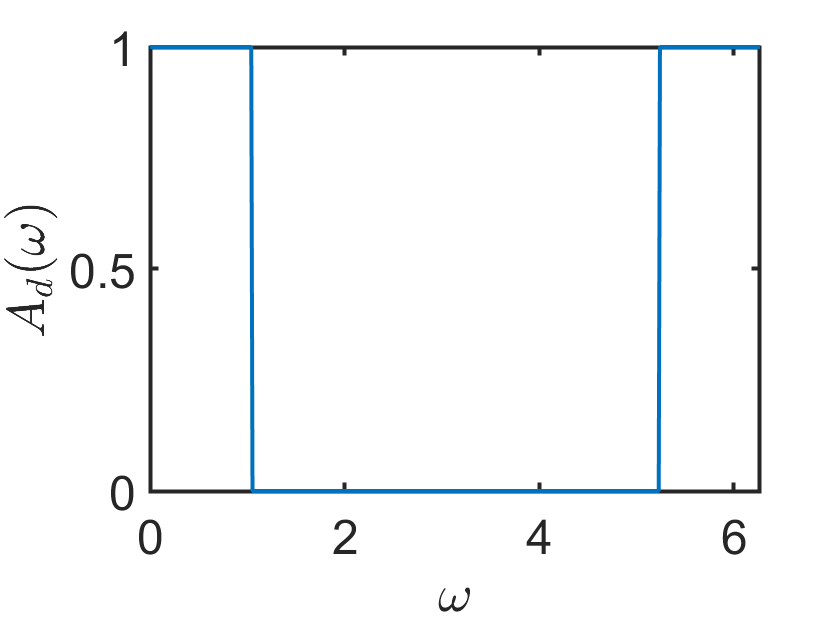


%Ideal (desired) response
figure
wset = 2*pi/501*(0:500);
plot(wset,(wset<=wc) | (wset>=2*pi-wc))
set(gca,'FontSize',24)  %enlarge figure font size
xlabel('$\omega$','interpreter','latex'); ylabel('$A_d(\omega)$','interpreter','latex')
set(findall(gcf,'-property','linewidth'),'linewidth',2) %makes the lines visible

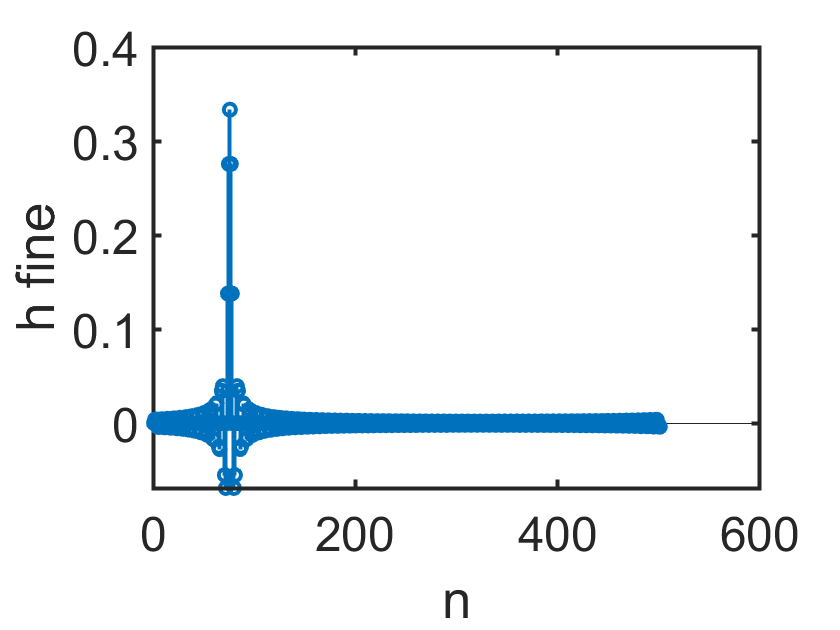





%%
%Method II: Truncation

A_fine = (wset<=wc) | (wset>=2*pi-wc);
Theta_fine = 75*wset;
H_fine = A_fine.*exp(-1i*Theta_fine);

%A fine graunularity impulse response
h_fine = real(ifft(H_fine)); %real 
figure
stem(h_fine)
xlabel('n'); ylabel('h fine')
set(gca,'FontSize',24)  %enlarge figure font size
set(findall(gcf,'-property','linewidth'),'linewidth',2) %makes the lines visible

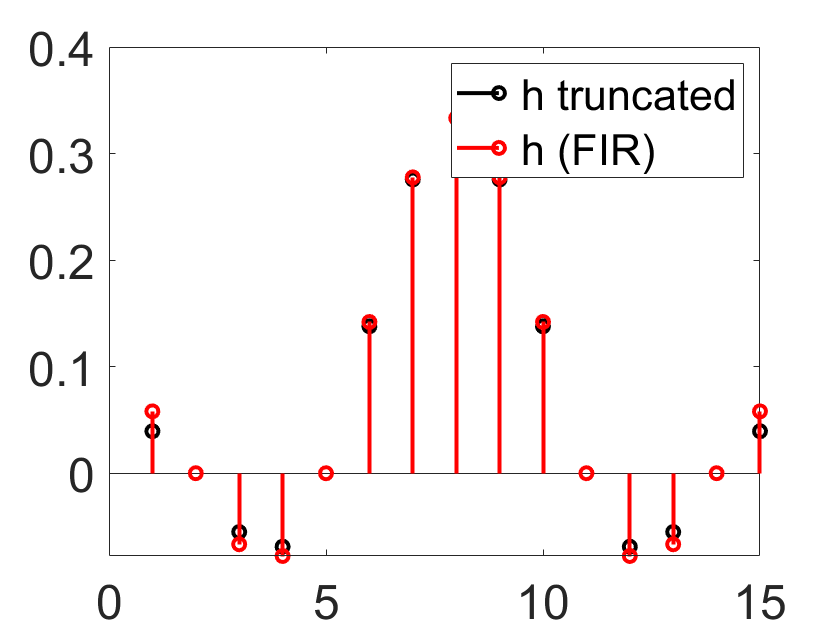


%Truncated impulse response
h_trunc = h_fine(76+(-7:7)); %retain only the middle N=15 samples 
figure
stem(h_trunc,'k','linewidth',2)
hold on
stem(h,'r','linewidth',2) %linear phase FIR filter with N taps we designed
legend('h truncated ','h (FIR)')
set(gca,'FontSize',24)  %enlarge figure font size

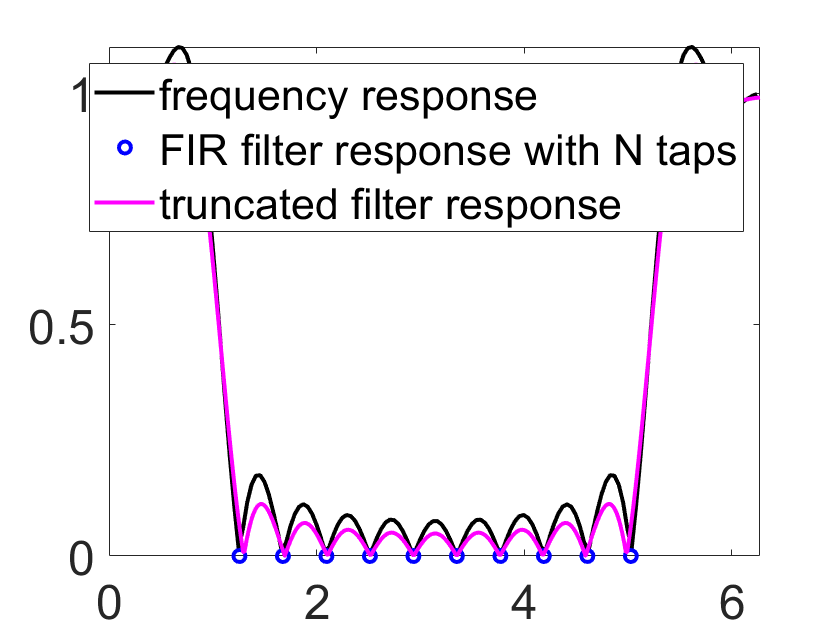


%Truncated frequency response
H_trunc = freqz(h_trunc,1,wset);

%Comment on the error
figure
plot(2*pi/151*(0:150),abs(Hout),'k','linewidth',2)
hold on;
plot(w,A,'bo','linewidth',2)
hold on;
plot(wset,abs(H_trunc),'m','linewidth',2)
legend('frequency response','FIR filter response with N taps','truncated filter response')
set(gca,'FontSize',24)  %enlarge figure font size

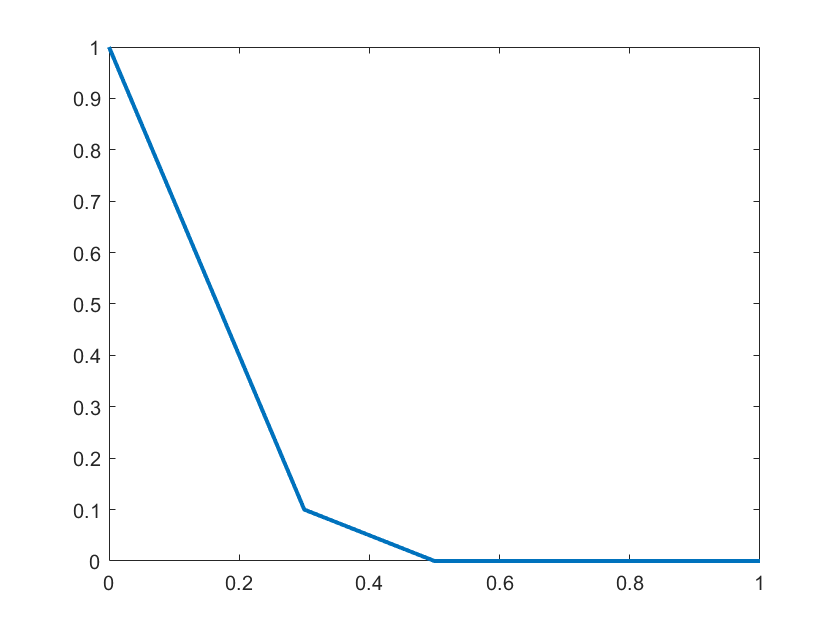



%%
%Method III: Chebyshev's approximation

N = 15; %number of taps
edges = [0 .3 .5 1];
values = [1 .1 0 0];
figure
plot(edges,values,'linewidth',2)

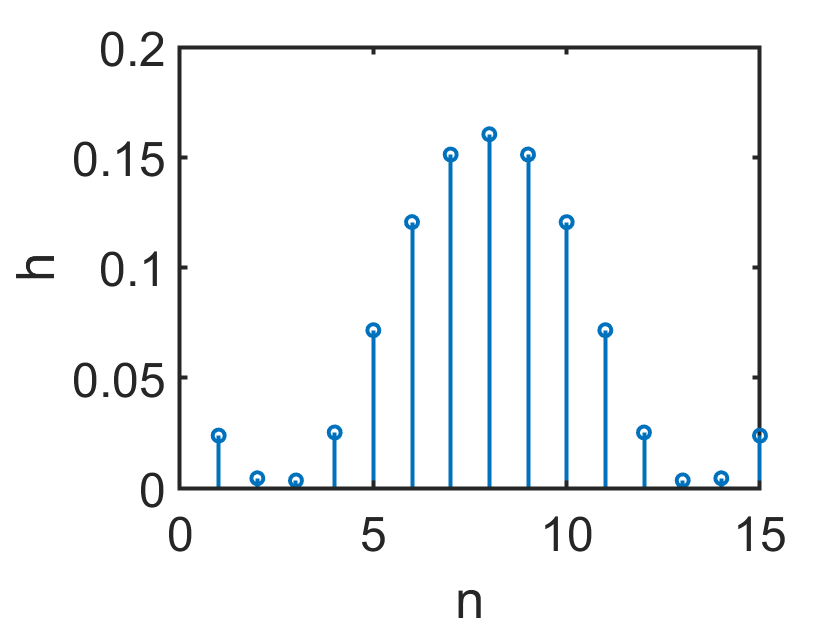



%Parks-McClellan optimal equiripple FIR filter design
b = firpm(N-1,edges,values);
figure
stem(b)
xlabel('n'); ylabel('h')
set(gca,'FontSize',24)  %enlarge figure font size
set(findall(gcf,'-property','linewidth'),'linewidth',2) %makes the lines visible

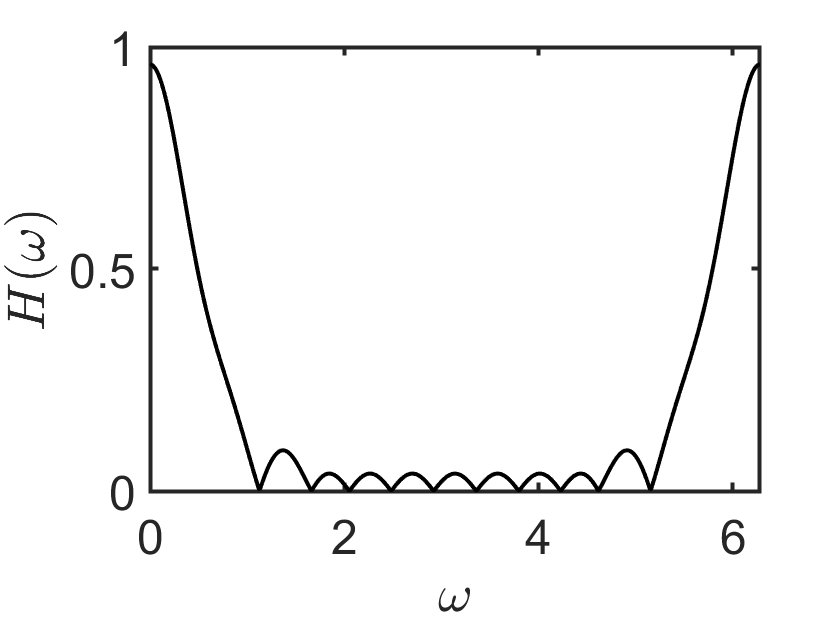



%Frequency response
w = linspace(0,2*pi,500); %from 0 to 2pi, 500 points
H = freqz(b,1,w);
figure
plot(w,abs(H),'k','linewidth',2);
xlabel('$\omega$','interpreter','latex'); ylabel('$H(\omega)$','interpreter','latex')
set(gca,'FontSize',24)  %enlarge figure font size
set(findall(gcf,'-property','linewidth'),'linewidth',2) %makes the lines visible


fdatool;